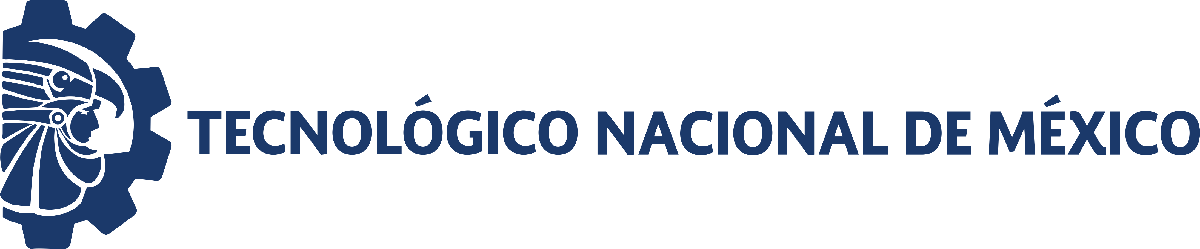                                 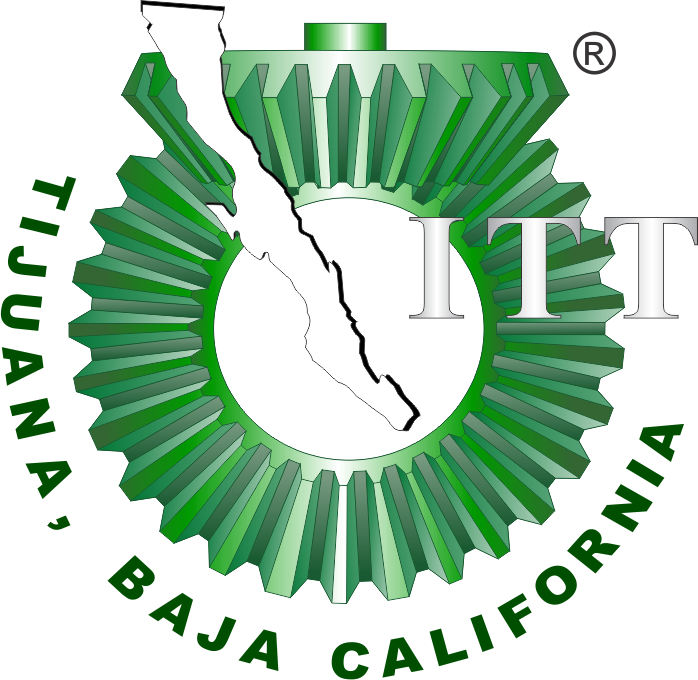

# Práctica 4: Regeneracion de Globulos Rojos

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

[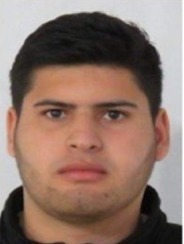]

Nombre del alumno: Jesus Javier Morales Lozoya

Número de control: 20210806

Correo institucional: **jesus.moralesl201@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = 180;
dt = 1E-3;
n= round(tend/dt);

%condisiones iniciales base para cada paciente
x1_0 = 59, x2_0 = 44; x3_0 = 885;

x1_0 = 59


% Parametros particulares para cada paciente
gamma = [0.769; 0.388; 0.510; 0.590; 0.262; 0.324; 0.356; 0.089; 0.243; 0.057];
beta = [1.650; 0.867; 1.617; 2.615; 1.518; 2.676; 0.891; 2.557; 0.925; 0.897];

% Condiciones iniciales alateorias 
seed = 2110806;%semilla para asegurar reproduccion
rng(seed,'twister');
%Intervalo de las condiciones iniciales
xmin = 0.99; xmax = 1.01;
interval = xmin + (xmax - xmin).*rand(numel(gamma),1);

%Condiciones iniciales para cada paciente 
x1_0 = x1_0*interval; disp('x1(0) = '); disp(x1_0');...
x2_0 = x2_0*interval; disp('x2(0) = '); disp(x2_0');...
x3_0 = x3_0*interval; disp('x3(0) = '); disp(x3_0');

x1(0) = 
   59.2165   59.5729   59.5227   58.4312   59.5699   58.5847   58.6300   59.3101   58.6813   59.2302



x2(0) = 
   44.1614   44.4272   44.3898   43.5758   44.4250   43.6903   43.7241   44.2313   43.7623   44.1716



x3(0) = 
  888.2468  893.5929  892.8401  876.4675  893.5481  878.7707  879.4499  889.6514  880.2198  888.4523



## Caso: Sin transfusion sanguinea[u(t)=0]

u = zeros(n+1,1);%No hay tranfusion
fig = 1;
for i = 1:10
    [t,x1,x2,x3] = system(x1_0(i),x2_0(i),x3_0(i),beta(i),gamma(i),u,dt,tend);
    plotdata(t,x1,x2,x3,fig)
end

## Caso: con transfusion sanguinea[u(t)=0]

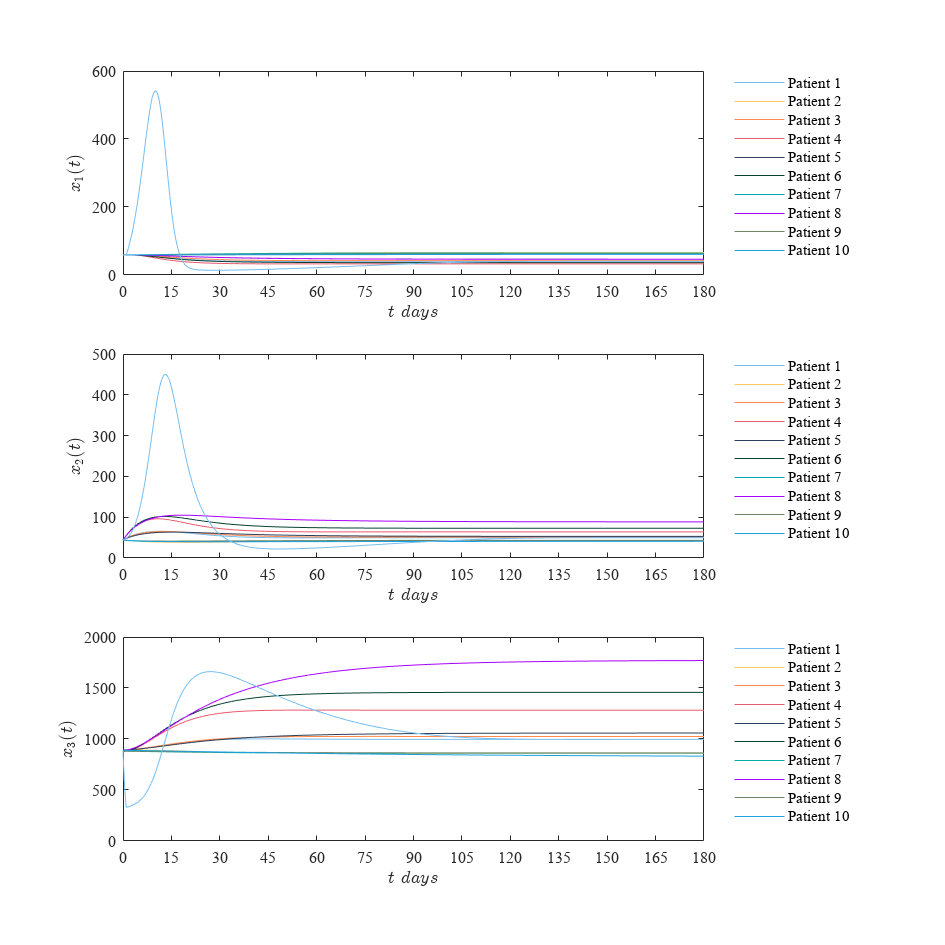

u2 = zeros(n+1,1); u2(1:1000) = 1; %Hay transfucion
fig = 2;
for i = 1:10
    [t,x1,x2,x3] = system(x1_0(i),x2_0(i),x3_0(i),beta(i),gamma(i),u2,dt,tend);
    plotdata(t,x1,x2,x3,fig)
end

## Funcion: Modelo Matematico


$${\dot{x} }_1 =\beta \left(X_0 -k_1 x_1 \right)+\frac{\left.{\gamma \left(B\right.}_{\textrm{ase}} -x_3 \right)\left(1-u\left(t\right)\right)x_1 }{B_{\textrm{ase}} }$$



$${\dot{x} }_2 =\beta \left(k_1 x_1 -k_2 x_2 \right)$$



$${\dot{x} }_3 =\beta \left(k_2 x_2 -{\alpha x}_3 \right)-u\left(t\right)x_3$$


function [t,x1,x2,x3] = system(x1_0,x2_0,x3_0,beta,gamma,u,dt,tend)
%Parametros fijos del sistema 
base =885.42; X0 = 7.3785; k1 = 0.125; k2 = 0.1667; alpha = 0.00833;
t = (0:dt:tend)';
n = round(tend/dt);
x1 = zeros(n+1,1); x1(1) = x1_0;
x2 = zeros(n+1,1); x2(1) = x2_0;
x3 = zeros(n+1,1); x3(1) = x3_0;

for i = 1:n
    x1(i+1) = x1(i) + (beta*(X0 - k1*x1(i))+ gamma*(base - x3(i))*(1 - u(i))*x1(i)/base)*dt;
    x2(i+1) = x2(i) + (beta*k1*x1(i)- k2*x2(i))*dt;
    x3(i+1) = x3(i) + (beta*(k2*x2(i) - alpha*x3(i))- u(i)*x3(i))*dt;
 end
end


## Funcion:Soluciones en el Tiempo

function plotdata(t,x1,x2,x3,fig)
 set(figure(fig),'Color','w')
 set(gcf,'Units','Centimeters','Position',[1,1,20,20])
mycolors = [119,190,240;
                255,203,97;
                255,137,79;
                234,91,111;
                45,64,89;
                6,66,50;
                0,171,169;
                170,0,255;
                109,135,100;
                27,161,226]/255;
 subplot(3,1,1);
 hold on; grid off; box on;colororder(mycolors);
 plot(t,x1);
 xlabel('$t$ ${days}$','Interpreter','latex','FontSize',10);
 ylabel('$x_1(t)$','Interpreter','latex','FontSize',10);
 xlim([0 180]); xticks(0:15:180);
 L = legend('Patient 1','Patient 2','Patient 3','Patient 4','Patient 5',...
     'Patient 6','Patient 7','Patient 8','Patient 9','Patient 10');
 set(L,'FontSize',9,'Box','off','Location','NorthEastOutside');
 set(gca,'FontName','Times New Roman','FontSize',10);

 subplot(3,1,2);
 hold on; grid off; box on;colororder(mycolors);
 plot(t,x2);
 xlabel('$t$ ${days}$','Interpreter','latex','FontSize',10);
 ylabel('$x_2(t)$','Interpreter','latex','FontSize',10);
 xlim([0 180]); xticks(0:15:180);
  L = legend('Patient 1','Patient 2','Patient 3','Patient 4','Patient 5',...
      'Patient 6','Patient 7','Patient 8','Patient 9','Patient 10');
 set(L,'FontSize',9,'Box','off','Location','NorthEastOutside');
 set(gca,'FontName','Times New Roman','FontSize',10);

 subplot(3,1,3);
 hold on; grid off; box on;colororder(mycolors);
 plot(t,x3);
 xlabel('$t$ ${days}$','Interpreter','latex','FontSize',10);
 ylabel('$x_3(t)$','Interpreter','latex','FontSize',10);
 xlim([0 180]); xticks(0:15:180);
  L = legend('Patient 1','Patient 2','Patient 3','Patient 4','Patient 5',...
      'Patient 6','Patient 7','Patient 8','Patient 9','Patient 10');
 set(L,'FontSize',9,'Box','off','Location','NorthEastOutside');
 set(gca,'FontName','Times New Roman','FontSize',10);

 % Exportar figuras
 if fig == 1
   exportgraphics(gcf,'Caso Sin transfucion.pdf','ContentType','vector')
   exportgraphics(gcf,'Caso Sin transfucion.png','ContentType','vector')
 elseif fig == 2
   exportgraphics(gcf,'Caso Con transfucion.pdf','ContentType','vector')
   exportgraphics(gcf,'Caso Con transfucion.png','ContentType','vector')
 end
end 
